# 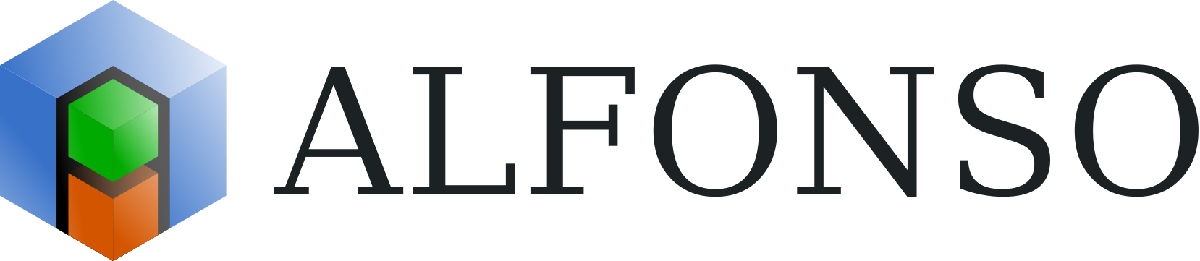

# ALFONSO - A versatile Formulation fOr N-dimensional Signal model fitting of MR spectroscopy data 

ALFONSO is a small class for processing and quantification of single-voxel magnetic resonance spectroscopy (MRS) measurements. The focus is on the convenient definition of model fitting strategies for the quantification of multi-dimensional MRS data.

## Quickstart guide

In this quickstart guide we will process and quantify a multi-TE STEAM MRS dataset which was acquired in a water-fat phantom. 

Add ALFONSO to the MATLAB path: 

addALFONSO2path();

Now read in the raw MRS data, which are in this case .data/.list files from a Philips MR scanner. Additionally, a .init was manually created to inform ALFONSO about some meta information that would otherwise be missing. 

mrs = ALFONSO('./tests/data/philips/data/al_19042022_1501389_12_1_wip_te_steamV4_raw_012.data');
mrs.read_data; % read in data

Let's display some information about the data we just read in: 

mrs.data_info % display some information

Data information:
-------------------------------------------------------------------
Patient ID: 
-------------------------------------------------------------------
Dimensions: x coil average TE
Dimension size: 2048 7 4 4
TE (ms): 10, 15, 20, 25
TM (ms): 16
TR (ms): 4000
Bandwidth (Hz): 3000 
Fieldstrength (T): 3 


As we can see here, the dataset has currently 4 dimensions (x is the sampling dimension, coils, averages and echo times (TE)). Also some very basic information about the timing is given: TE, TM and TR. This information was provided by the .ini file we manually had to create and which is not automatically exported by the scanner. 

### Processsing

Now can perform a few simple processing steps including coil combination and averaging:

mrs.coilcombination; % by perform the coil combination we will reduce the data dimensionality by one

Coil selection mode: manual
Coils used: 1  2  3  4  5  6  7 ( 7 / 7 coils)


mrs.averaging; % again, by perform the signal averaging we will reduce the data dimensionality by one

We can also plot the intermediate after these first two steps: 

Recognized the following dyanmics: x, TE


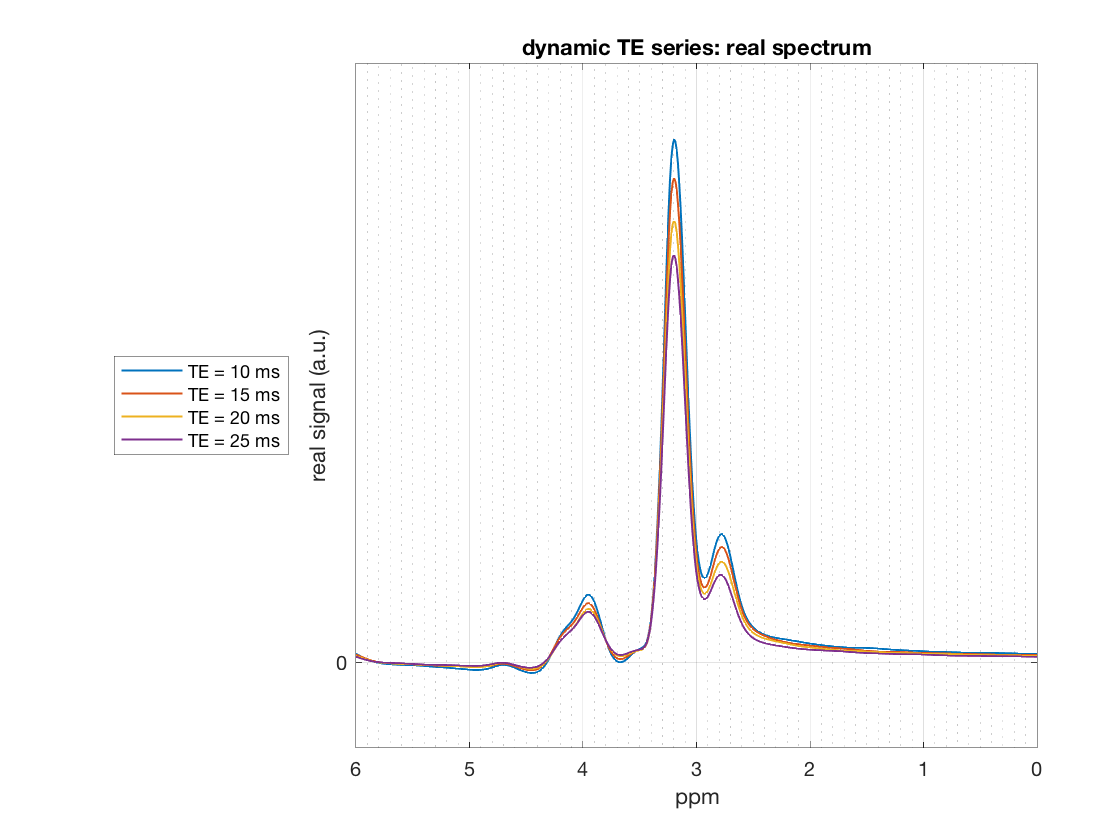

mrs.plot_dynSeries;

As we can see here, the ppm scale is off, because the center frequency was not correctly set during the acquisition. We will therefore try correct the center frequency of the spectra by referencing the spectra to the methylene fat peak at 1.30ppm:

mrs.set_ref_freq(1.3) % use methylene peak as reference

The corrected spectra will now look as following: 

Recognized the following dyanmics: x, TE


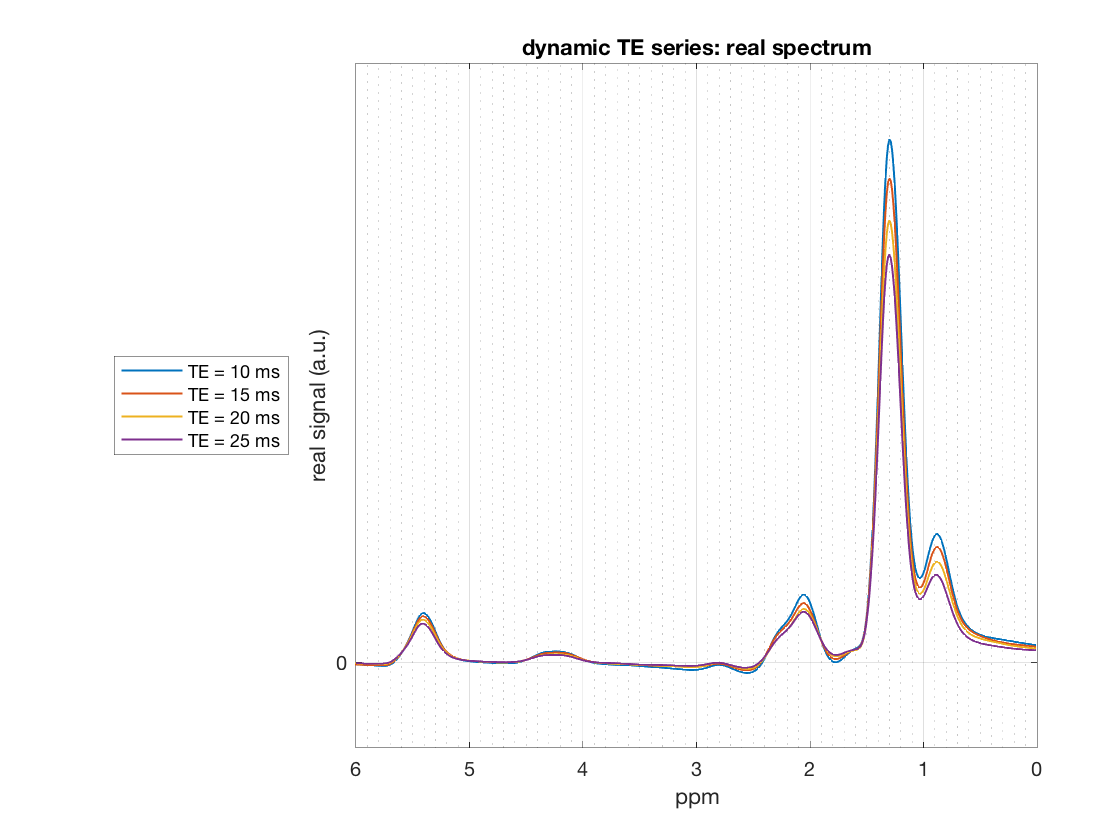

mrs.plot_dynSeries;

As a last step we will here perform a zero-order phase correction and plot the finial result of the processed spectrum:

Recognized the following dyanmics: x, TE


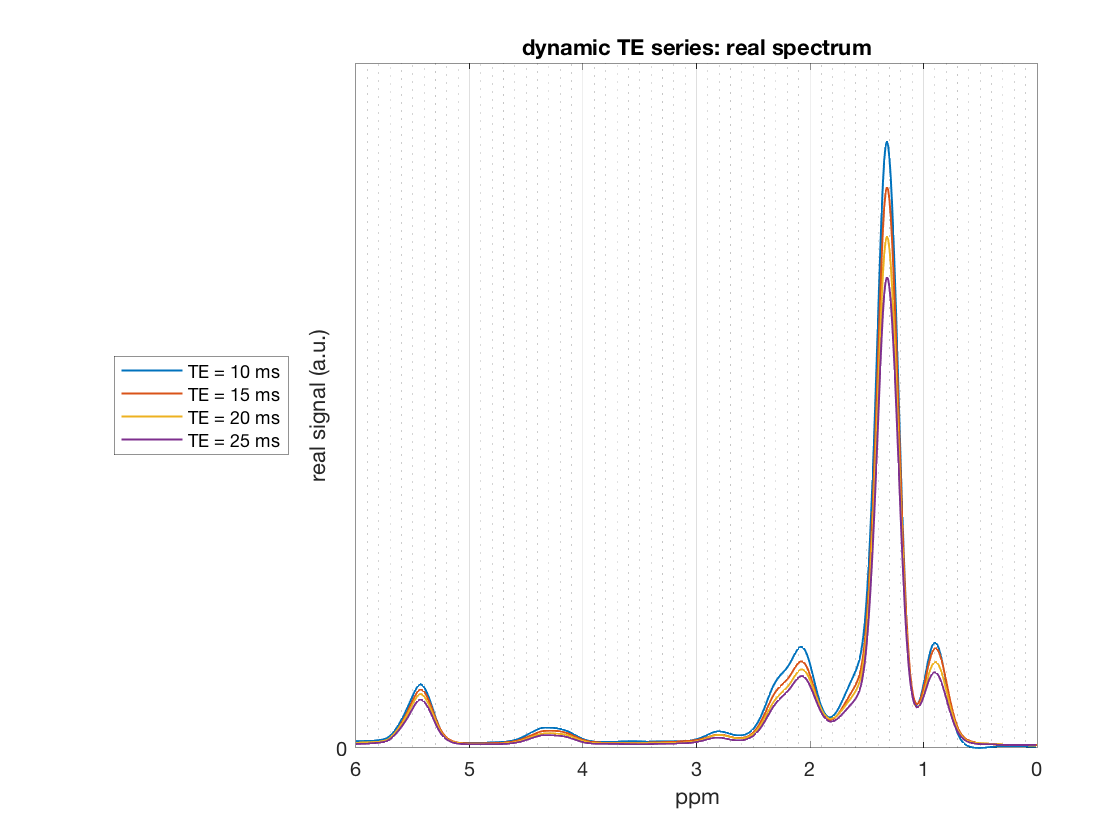

mrs.phase_correction;
mrs.plot_dynSeries;

### Quantification

The processed spectra will now be used in a subsequent quantification step. Here we take an example quantification model which constraints the peak amplitudes of the fat frequencies to the chemical triglyceride model. And also the T2 relaxation times will be constrained across peaks. 

Let's have a quick look at the model definition file to inspect the model: 

type ./examples/example_waterfat_TAG10_cT2.json


{
    "model_name": "example_waterfat_TAG10_cT2",
    "description": "Dynamic TE series for water-fat example MRS with triglyceride constrained rho and T2 constraints.",
    "author": "Stefan Ruschke (stefan.ruschke@tum.de)",
    "created_date": "Apr 21, 2022",
    "algorithm": "NL2SOL",
    "rho_constraint": "@(x) [(ALFONSO.model_TAG(x(1),x(2),x(3),10) .* exp(x(4))); exp(x(5))]",
    "rho_vars": [1, 2, 3, 4, 5],
    "rho_init": [1, 0.2, 12, 1, 0.5],
    "rho_lb": [0, 0, 10, 0, 0],
    "rho_ub": [6, 4, 40, 100, 100],
    "omega_ref": [0.88, 1.3, 1.59, 2.04, 2.25, 2.78, 4.10, 4.30, 5.19, 5.42, 4.67],
    "omega_vars": [14, 14, 14, 14, 14, 14, 14, 14, 14, 14, 15],
    "omega_init": [0],
    "omega_lb": [-0.2],
    "omega_ub": [0.2],
    "d_vars": [6, 7, 6, 6, 6, 6, 6, 6, 6, 6, 8],
    "d_init": [1],
    "d_lb": [0],
    "d_ub": [25],
    "g_vars": [9, 10, 9, 9, 9, 9, 9, 9, 9, 9, 11],
    "g_init": [1],
    "g_lb": [0],
    "g_ub": [25],
    "T2_vars": [12, 12, 12, 12, 12, 12, 12, 12, 12

Let's load the model and then perform the model fitting.

% perform quantification
mrs.set_model('./examples/example_waterfat_TAG10_cT2.json', 1) % load quantification model from JSON file
mrs.fit_model; % perform actual fitting

NL2SOL v2.13 - Settings
  Maximum function evaluations: 1000000
  Maximum iterations:           400
  Absolute function tolerance:  1.000000e-10
  Relative function tolerance:  1.000000e-10
  X tolerance:                  1.000000e-08
  Jacobian:                     Finite differencing
  Bounds:                       Enabled

Exit criterion: Below function tolerance
Final SSE: 0.680212. Function evaluations: 501. Jacobian evaluations: 0


We can visualize the model fitting result as follows: 

Recognized the following dyanmics: x, TE


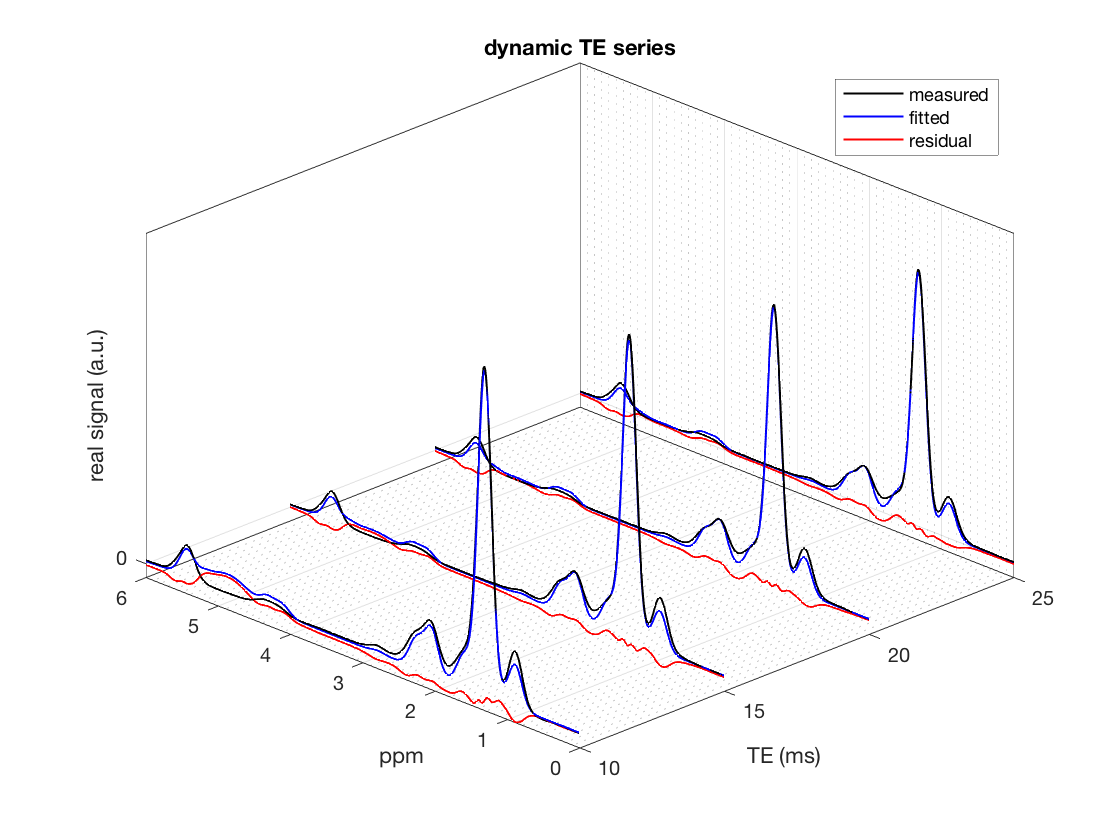

mrs.plot_fit_model; % display model fitting resul

The quantification results are stored together with the data in the object and can be accessed as follows: 

mrs.quant{1}.output.param

ans = struct with fields:
      rho: [11×1 double]
    omega: [0.8979 1.3179 1.6079 2.0579 2.2679 2.7979 4.1179 4.3179 5.2079 5.4379 4.8700]
        d: [0 1.1377 0 0 0 0 0 0 0 0 25]
        g: [12.1647 11.6404 12.1647 12.1647 12.1647 12.1647 12.1647 12.1647 12.1647 12.1647 25]
      phi: 0.0096
       T2: [0.0593 0.0593 0.0593 0.0593 0.0593 0.0593 0.0593 0.0593 0.0593 0.0593 0.0050]


This concludes the quick start guide. Additional information and documentation can be also found in the "getting started" section which discusses a few selected topics and also in the documentation. 

## Overview

ALFONSO's main functionality can be divided into the following three categories: 

- Processing

- Quantification 

- Visualization

- Helper

where *processing* includes all methods that are used for data preparation, *quantification* includes methods for signal model definition and fitting, *visualization* includes methods for plotting spectral and fitting information and *helper* including methods for data handling (e.g. importing / exporting of data) and misc. 

A list of existing methods is given in the following. 

### Processing methods

- ALFONSO.apodization() - signal apodization (usually not recommended)  

- ALFONSO.averaging() - averaging along the average dimension 

- ALFONSO.coilcombination() - method for combining multiple receiver coils

- ALFONSO.frequency_offset_correction() - correction of frequency shift along dynamic dimensions

- ALFONSO.phase_correction() - zero order phase correction method

- ALFONSO.polaritycombination() - combination of opposite diffusion encoding directions (for eddy current compensation)

- ALFONSO.set_ref_freq() - reference frequency determination / setting

- ALFONSO.read_data() - function to read data from supported raw data file

See also a very basic processing pipeline using some of the above methods is given in ALFONSO.process(). 

### Quantification methods

- ALFONSO.set_model() - load model definition 

- ALFONSO.fit_model() - perform model fitting based on the loaded model definition 

### Visualization methods

- ALFONSO.plot_dyn() - plot a specific dynamic

- ALFONSO.plot_dynSeries() - plot a dynamic series

- ALFONSO.plot_fit_model() - plot model fitting result (required to run fit_model() first)

### Helper methods

- ALFONSO.data_info() - displays basic data information

- ALFONSO.add_noise() - adds noise to the data (e.g. for Monte Carlo simulations)

- ALFONSO.get_SNR() - determines signal to noise ratio in the data

- ALFONSO.save_plots() - saves all open plots

- ALFONSO.save_obj() - saves object as a mat file (can be read again using load_obj())

- ALFONSO.save_model() - exports the quantification model from quant{cur_quant}.model.param to a file

- ALFONSO.load_obj() - reads an object from an object mat file

## Model definition cook book

ALFONSO models can be conveniently be defined using JSON files. Therefore, a short definition of the ALFONSO signal model is given in the following. 

### Signal models in ALFONSO

In order to do so, ALFONSO is handling signal models in the following way: The measured signal $S$ is defined as


$$S = \sum_{m=1}^M \Upsilon_m \Theta_m$$


where $\Upsilon_m
$ is the free induction decay function 


$$\Upsilon\left(t_n\right) = \varrho_m e^{i 2 \pi \omega_m t_n} e^{i \phi_m}  e^{-\left( d_m + \frac{1}{2} g_m^2 t_n  \right) t_n} + \epsilon,$$


and $\Theta_m$ is the product of sequence specific modulator function, e.g.

$\Theta_m^{\text{TI}} = \left( 1 - 2 e^{- T_I T_{1,m}^{-1}} \right)$ for inversion recovery signal weighting or $\Theta_m^{\text{TE}} = e^{- T_E T_{2,m}^{-1}}$ for an echo time weighted signal. 

In ALFONSO we define a model $M\left( x \right)$as $M\left( x \right) = S\left( \Psi\left( x \right) \right)$where we use a mapping function $\Psi$ to map the variable vector $x$  onto the signal $S$. 

The mapping function $\Psi$ is basically what is defined in the model definition file (plus e.g. optional model dimensions etc.) and therefore need to map the fitting vector $x$  on all used parameters of the signal $S$: 


$$\Psi\left( x \right)
\rightarrow
\left[\begin{array}{c}
        \rho\\
        \omega\\
        \phi\\
        d\\
        g\\
        T_1\\
        T_2\\
        D\\
        \vdots
\end{array}\right]
$$


For convenience, the first 6 dimension of $M\left( x \right)$are predefined as given below. All other dimensions can be freely defined in the model definition file. 


$$\begin{array}{llll}
\text{dimension} & \text{parameter} & \text{function} & \text{description} \\ 
1 & M & \text{species} & \text{separate species signals} \\  
2 & t & \Upsilon & \text{time domain signal} \\
3 & TI & \Theta^{\text{TI}} & \text{inversion recovery modulation} \\ 
4 & TE & \Theta^{\text{TE}} & \text{echo time modulation} \\
5 & TM & \Theta^{\text{TM}} & \text{mixing time modulation} \\
6 & b-value & \Theta^{\text{b-value}} & \text{diffusion weighting modulation} \\
\vdots & \vdots & \vdots & \text{free to define}
\end{array}$$


### Model definition 

The model definition file holds the information on the variable mapping $\Psi(x)$ plus some additional information including initial values and bounds (if supported by the solver) and meta data (model name, author, ...). 

The provided model_template.json includes examples for all possible model attributes. Please note, that this template is non-functional (e.g. lower / upper bounds should not be defined together with constraints) and only serves as reference.  

Let's have a look at model_template.json to understand the anatomy of a model: 

type models/model_template.json


{
    "model_name": "model_template",
    "description": "This template includes all parameters that can be modeled. It is not functional! Delete a parameters as needed. 
Bounds (_lb,_ub) and _constraint cannot be used simultanously.
The Theta functions are given for reference and can be removed if remained unchanged.",
    "author": " (John Doe john.doe@email.com)",
    "created_date": "01-Jan-1970",
    "last_update_date": "01-Jan-2000",
    "algorithm": "levenberg-marquardt",
    "rho_vars": [1, 2],
    "rho_init": [0.5],
    "rho_constraint": "@(x) exp(x(modelparam.rho_vars))",
    "rho_inv_constraint": "@(x) log(x(modelparam.rho_vars))",
    "rho_lb": [0],
    "rho_ub": [Inf],
    "omega_ref": [1.30, 4.67],
    "omega_vars": [3, 4],
    "omega_init": [0],
    "omega_constraint": "@(x) ALFONSO.bound_tanh(x(modelparam.omega_vars), -0.2, 0.2)",
    "omega_inv_constraint": "@(x) ALFONSO.bound_inv_tanh(x(modelparam.omega_vars), -0.2, 0.2)",
    "omega_lb": [-0.2],
    "omega_ub": [0.2

The parameter names {rho,omega,phi,d,g,T1,T2,D} are the same as given in the section Signal models in ALFONSO. Please note that all initial values ({}_init) have to be given in SI units (e.g. T1 / T2 in seconds).

The model definition shows the following meta data fields: 

- model_name - (required) freely chosen string to describe the model 

- description - (optional) description of the model 

- author - (optional) model author 

- created_date - (optional) string data of creation

- last_update_date - (optional) string date of last change in the model

Model defining fields:

- {}_vars - Variable mapping for the given parameter. vector of the indices of variable vector $x
$. 

- omega_ref - Reference frequency of species given in ppm. 

- {}_constraint - Constraints on the parameters.  

- {}_inv_constraint - Inverse function of {}_constraint, which is used to transform {}_init.

- add_model_param - Defines additional custom model parameters (rho, phi, omega, d, g, T1, T2, D are already predefined). {}_vars, {}_init, {}_constraint, {}_inv_constraint,  {}_lb and {}_ub have / can to be correspondingly defined.

- add_model_param - Defines additional custom model parameters (rho, phi, omega, d, g, T1, T2, D are already predefined). 

- {}_func - Theta function overloading. The example functions are the default functions, are only given for reference and do not have to be provided. Currently only the following Theta function can be overloaded: TI, TE, TM, bvalue

Solver specific fields:

- algorithm - Solver used for model fitting. Matlab supports out of the box 'levenberg-marquardt' and 'trust-region-reflective'. 'NL2SOL' can also be used if compiled properly. See ./lib/mexNL2SOL/ for more details. 

- {}_init - Initial values for the given parameters. Has to have the same length as corresponding {}_vars vector.  

- {}_lb, {}_ub - Lower (lb) and upper (ub) bounds to be used be the solver (if supported by the solver). 

The following fields have to yield the same vector length or a scalar: 

- {}_vars, exception: {}_vars can have a length greater 0 if {}_constraint and {}_inv_constraint are defined and ensure the requirement. 

- omega_ref 

- {}_init

- {}_lb and {}_ub

- {}_constraint and {}_inv_constraint 

Please see also example models under *./models/ *for more examples on how to define models. 

### Useful helper functions for model definition

Useful helper functions for imposing parameter constraints that are already included in ALFONSO include: 

- ALFONSO.bound_tanh() - tanh as bound function

- ALFONSO.bound_inv_tanh() - inverse of a tanh bound function

- ALFONSO.model_TAG() - triglyceride model function 

- ALFONSO.model_mitra() - restricted diffusion model by Mitra

- ALFONSO.model_murdaycotts() - restricted diffusion model by Murday and Cotts

## How to implement your own processing methods

Custom processing methods can be easily implemented using already existing helper functions. The usual workflow consists of three steps: data retrieval, data manipulation, writing back data to the object. The most important convenience methods supporting this workflow include: 

- ALFONSO.get_data() - convenience function to get data array

- ALFONSO.set_data() - convenience function to write data array

- ALFONSO.is_data_dim() - convenience function to check if a given dimension exists in the data

- ALFONSO.get_ppm_scale() - convenience function to update the ppm reference 

An example template for a custom method that just manipulates some data could look like this:

function my_custom_function1( this )
%MY_CUSTOM_FUNCTION1 performs a custom operation on the data
%   Detailed description follows here ...


%% get data (FID array)
FID = this.get_data({'x','coil','average'}); % will return a 4 dimensional FID array (samples, coils, averages, all other dims)

%% manipulate data
% PPM = this.scanparam.ppm_rel; % get the ppm scale of the spectrum
FID(:,:,2:2:end,:) = FID(:,:,2:2:end,:) ./ 2; % divide every second average by 2

%% write back manipulated data (and inform about the new dimension)
this.set_data(FID, {'x','coil','average'})

end

An example template for a custom method that introduces a new dimension could look like this:

function my_custom_function2( this, factor )
%MY_CUSTOM_FUNCTION2 performs a custom operation on the data
%   Detailed description follows here ...

%% get data
FID = this.get_data({'x','average'}); % will return a 3 dimensional FID array (samples, averages, all other dims)

%% manipulate data or data dimensionality

% add a copy of the average dimension as additional dimension
FID = permute(FID,[1 2 4 3]); % now we have a 4 dimensional array (samples, average, 1, all other dims)
FID = cat(3,FID,FID); % here we just duplicate the array along the 3rd dimension (samples, average, 2, all other dims)

% manipulate some data
FID(:,:,2,:) = FID(:,:,2,:) ./ factor; % just divide by factor

%% write back manipulated data (and inform about the new dimension)
this.set_data(FID, {'x','average','my-custom-dimension'}) % will write a 4 dimensional FID array (samples, averages, my-custom-dimension, all other dims)

end

## How to implement a custom raw data reader

The data import logic is implemented under ALFONSO.read_data(). It is recommended that a custom function is written that returns the actual data and meta information (see under the directory .*/lib/io/* for existing examples) which is called from ALFONSO.read_data(). In read_data() the actual data reader is selected based on the file extension. An example is given below:

## Copyright

Copyright (c) 2022 Stefan Ruschke

## License

see [License](matlab:open("License"))